clear; clc; close all;

### Data Extraction from structs

% Load data
rot = load("calib1_rotate.mat");
straight = load("calib2_straight.mat");

% Task 1
task1_1 = load("task1_1.mat");
task1_2 = load("task1_2.mat");
task1_3 = load("task1_3.mat");
task1_4 = load("task1_4.mat");
task1_5 = load("task1_5.mat");

% Task 2
task2_1 = load("task2_1.mat");
task2_2 = load("task2_2.mat");
task2_3 = load("task2_3.mat");
task2_4 = load("task2_4.mat");
task2_5 = load("task2_5.mat");

% Output file
outputFileName = 'calib_params.mat';

% Stationary Period in straight calibration
stationary_idx = find(straight.out.GT_time.time==60);
time = straight.out.GT_time.time;

## Accelerometer Calibration

Goal: Subtract bias from z-axis acceleration measured that it only contains gravity

% Load data
% The first column flunctuates the least around gravity acceleration,
% indicating x-axis in sensor frame as z-axis in global frame

accel_raw = squeeze(straight.out.Sensor_ACCEL.signals.values)';
accel_stationary = accel_raw(1:stationary_idx,:);
g = [9.81, 0, 0];

% Find bias and variance
accel_mean = mean(accel_stationary);
accel_bias = accel_mean - g             % Remove difference with gravity from Z

accel_bias =     0.1925    0.0275   -0.3963


accel_var = var(accel_stationary)       % Determine noise in process model

accel_var = 1.0e-03 *

    0.1910    0.0456    0.0697


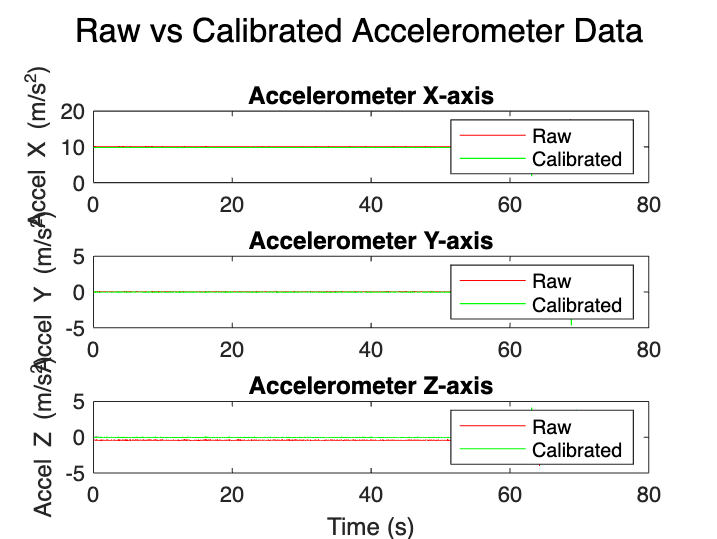


% Calibrate full dataset
time_accel = straight.out.Sensor_ACCEL.time;
calib_accel = accel_raw - accel_bias;

figure;
subplot(3,1,1);
plot(time_accel, accel_raw(:,1), 'r'); hold on;
plot(time_accel, calib_accel(:,1), 'g');
ylabel('Accel X (m/s^2)');
legend('Raw', 'Calibrated');
title('Accelerometer X-axis');

subplot(3,1,2);
plot(time_accel, accel_raw(:,2), 'r'); hold on;
plot(time_accel, calib_accel(:,2), 'g');
ylabel('Accel Y (m/s^2)');
legend('Raw', 'Calibrated');
title('Accelerometer Y-axis');

subplot(3,1,3);
plot(time, accel_raw(:,3), 'r'); hold on;
plot(time, calib_accel(:,3), 'g');
ylabel('Accel Z (m/s^2)');
xlabel('Time (s)');
legend('Raw', 'Calibrated');
title('Accelerometer Z-axis');

sgtitle('Raw vs Calibrated Accelerometer Data');

## Gyroscope Calibration

Recorded at 104 Hz

% Load data
gyro_raw = squeeze(straight.out.Sensor_GYRO.signals.values)';
gyro_stationary = gyro_raw(1:stationary_idx, :);

% Find bias and variance
gyro_bias = mean(gyro_stationary)

gyro_bias =     0.0019   -0.0112   -0.0013


gyro_var = var(gyro_stationary)

gyro_var = 1.0e-05 *

    0.1159    0.1949    0.1492


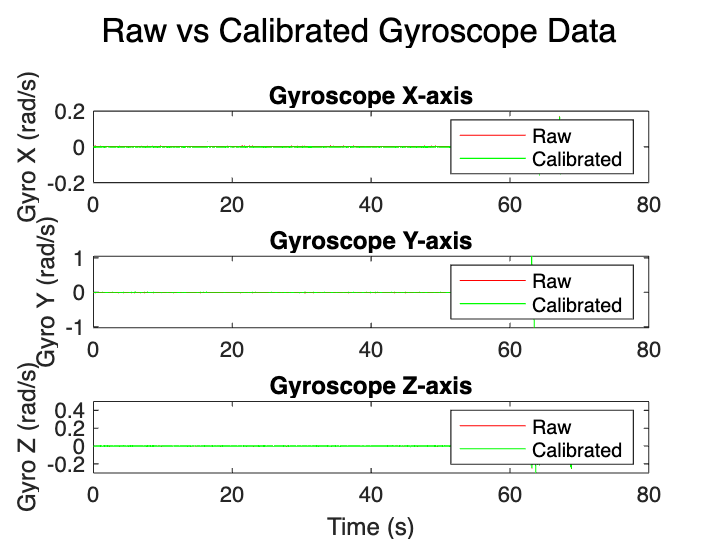


% Calibrate full dataset
calib_gyro = gyro_raw-gyro_bias;
time_gyro = straight.out.Sensor_GYRO.time;

figure;
subplot(3,1,1);
plot(time_gyro, gyro_raw(:,1), 'r'); hold on;
plot(time_gyro, calib_gyro(:,1), 'g');
ylabel('Gyro X (rad/s)');
legend('Raw', 'Calibrated');
title('Gyroscope X-axis');

subplot(3,1,2);
plot(time_gyro, gyro_raw(:,2), 'r'); hold on;
plot(time_gyro, calib_gyro(:,2), 'g');
ylabel('Gyro Y (rad/s)');
legend('Raw', 'Calibrated');
title('Gyroscope Y-axis');

subplot(3,1,3);
plot(time_gyro, gyro_raw(:,3), 'r'); hold on;
plot(time_gyro, calib_gyro(:,3), 'g');
ylabel('Gyro Z (rad/s)');
xlabel('Time (s)');
legend('Raw', 'Calibrated');
title('Gyroscope Z-axis');

sgtitle('Raw vs Calibrated Gyroscope Data');

## ToF Calibration

Goal: calculate ToF offset and export set of params for calibration in trials

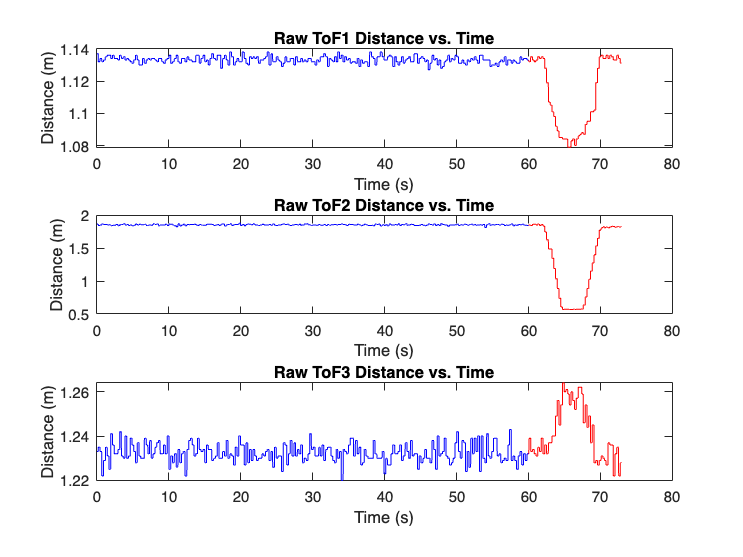

% Load data
ToF_time = straight.out.Sensor_Time.time;
idx_minute = find(ToF_time==60);
ToF1_raw = straight.out.Sensor_ToF1.signals.values;
ToF2_raw = straight.out.Sensor_ToF2.signals.values;
ToF3_raw = straight.out.Sensor_ToF3.signals.values;

% Visualize raw values - noisy data
figure;
subplot(3,1,1)
plot(ToF_time(1:idx_minute), ToF1_raw(1:idx_minute,1), 'b', ToF_time(idx_minute:end), ToF1_raw(idx_minute:end,1),'r')
xlabel('Time (s)')
ylabel('Distance (m)')
title('Raw ToF1 Distance vs. Time')

subplot(3,1,2)
plot(ToF_time(1:idx_minute), ToF2_raw(1:idx_minute,1), 'b', ToF_time(idx_minute:end), ToF2_raw(idx_minute:end,1),'r')
xlabel('Time (s)')
ylabel('Distance (m)')
title('Raw ToF2 Distance vs. Time')

subplot(3,1,3)
plot(ToF_time(1:idx_minute), ToF3_raw(1:idx_minute,1), 'b', ToF_time(idx_minute:end), ToF3_raw(idx_minute:end,1),'r')
xlabel('Time (s)')
ylabel('Distance (m)')
title('Raw ToF3 Distance vs. Time')

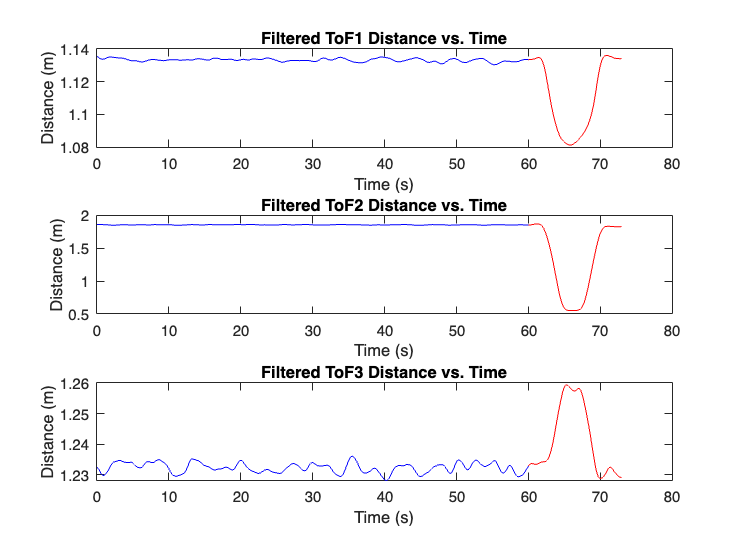


% Apply butterworth filter on noisy data before calibration
ToF1_filt = butterworth(ToF1_raw);
ToF2_filt = butterworth(ToF2_raw);
ToF3_filt = butterworth(ToF3_raw);

figure;
subplot(3,1,1)
plot(ToF_time(1:idx_minute), ToF1_filt(1:idx_minute,1), 'b', ToF_time(idx_minute:end), ToF1_filt(idx_minute:end,1),'r')
xlabel('Time (s)')
ylabel('Distance (m)')
title('Filtered ToF1 Distance vs. Time')

subplot(3,1,2)
plot(ToF_time(1:idx_minute), ToF2_filt(1:idx_minute,1), 'b', ToF_time(idx_minute:end), ToF2_filt(idx_minute:end,1),'r')
xlabel('Time (s)')
ylabel('Distance (m)')
title('Filtered ToF2 Distance vs. Time')

subplot(3,1,3)
plot(ToF_time(1:idx_minute), ToF3_filt(1:idx_minute,1), 'b', ToF_time(idx_minute:end), ToF3_filt(idx_minute:end,1),'r')
xlabel('Time (s)')
ylabel('Distance (m)')
title('Filtered ToF3 Distance vs. Time')

% Load GT Straight Line position
GT_time = straight.out.GT_time.time; % Same as sensor time increments
GT_straight = straight.out.GT_position.signals.values(1:idx_minute,:); % Only take stationary data for calibration
GT_rot = straight.out.GT_rotation.signals.values(1:idx_minute,:); % [W,X,Y,Z]
GT_x = GT_straight(:,1);
GT_y = GT_straight(:,2);
GT_z = GT_straight(:,3); % Most likely not used, no movement along z-axis

% Parameters for optimization
P = [GT_x, GT_y];
eul = quat2eul(GT_rot);  % [yaw, pitch, roll]
Yaw = eul(:,1).*ones(idx_minute,1); % Going straight, yaw is constant

% Optimization
% Calculate reflection point for where ToF hits wall
% Initial guess (meters)
x0 = [0.1, 0.1, 0.1];

% Optimize with root mean squared error (only stationary)
optimal_offsets = fminsearch(@(x) offset_cost_to_arena(x, ToF1_filt(1:idx_minute,:), ToF3_filt(1:idx_minute,:), ToF2_filt(1:idx_minute,:), Yaw, P), x0);

disp('Optimal sensor offsets:');

Optimal sensor offsets:


fprintf('Left:  %.3f m\n', optimal_offsets(1));

Left:  -1.166 m


fprintf('Right: %.3f m\n', optimal_offsets(2));

Right: -1.241 m


fprintf('Front: %.3f m\n', optimal_offsets(3));

Front: -3.982 m


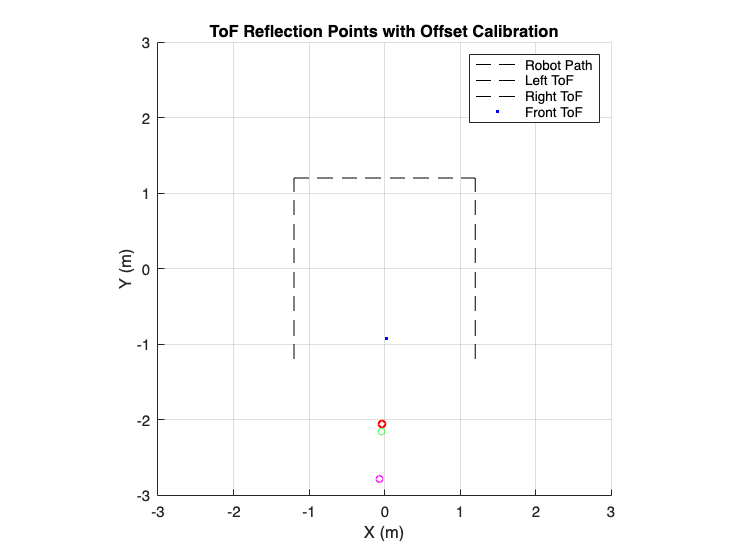


% Plot ground truth and ToF
% Robot moving diagonal (theta) in straight line
[R_left_0, R_right_0, R_front_0] = plot_reflection_points(ToF1_filt(1:idx_minute,:), ToF3_filt(1:idx_minute,:), ToF2_filt(1:idx_minute,:), Yaw, P, [0 0 0]);

[R_left, R_right, R_front] = plot_reflection_points(ToF1_filt(1:idx_minute,:), ToF3_filt(1:idx_minute,:), ToF2_filt(1:idx_minute,:), Yaw, P, optimal_offsets);


% Configure optimized offsets for export
tof_bias = optimal_offsets

tof_bias =    -1.1664   -1.2412   -3.9824


## Magnetometer Calibration

Goal: Calculate soft iron and hard iron matrices

%% OPTIMIZE %%
% Load data
time_rot = rot.out.Sensor_MAG.time;
mag_raw = squeeze(rot.out.Sensor_MAG.signals.values)';

fprintf('*Assumption*: Magnetometer data in global frame is [Z,Y,X] when sensor frame is [X,Y,Z].')

*Assumption*: Magnetometer data in global frame is [Z,Y,X] when sensor frame is [X,Y,Z].

mag_raw_2D = [mag_raw(:,3), mag_raw(:,2)];
[mag_cal, mag_params] = calibrateMagnetometer2D(mag_raw_2D);

% Check yaw calibration
figure;
subplot(1,2,1); % Plot raw magnetometer ellipse
plot(mag_raw_2D(:,1), mag_raw_2D(:,2), 'r.');
xlabel('x (T)'); ylabel('y (T)');
title('Raw Magnetometer'); axis equal; grid on;

subplot(1,2,2)
plot(mag_cal(:,1), mag_cal(:,2), 'r.')
xlabel('x (T)'); ylabel('y (T)');
title('Calibrated Magnetometer'); axis equal; grid on;

%% CHECK GENERALIZE %%
% Check matrix generalization
time_1 = task1_1.out.Sensor_MAG.time;
data = squeeze(task1_1.out.Sensor_MAG.signals.values)';
data_2D = [data(:,3), data(:,2)]

data_2D = 1.0e-03 *

    0.0681   -0.0448
    0.0681   -0.0448
    0.0679   -0.0451
    0.0679   -0.0451
    0.0679   -0.0451
    0.0679   -0.0451
    0.0682   -0.0450
    0.0682   -0.0450
    0.0682   -0.0450
    0.0682   -0.0450


mag_cal_1 = calibrate_mag_params(mag_params, data_2D)

mag_cal =     1.1990    1.1350
    1.1990    1.1350
    1.1545    1.0963
    1.1545    1.0963
    1.1545    1.0963
    1.1545    1.0963
    1.1764    1.1038
    1.1764    1.1038
    1.1764    1.1038
    1.1764    1.1038


mag_cal_1 =     1.1990    1.1350
    1.1990    1.1350
    1.1545    1.0963
    1.1545    1.0963
    1.1545    1.0963
    1.1545    1.0963
    1.1764    1.1038
    1.1764    1.1038
    1.1764    1.1038
    1.1764    1.1038


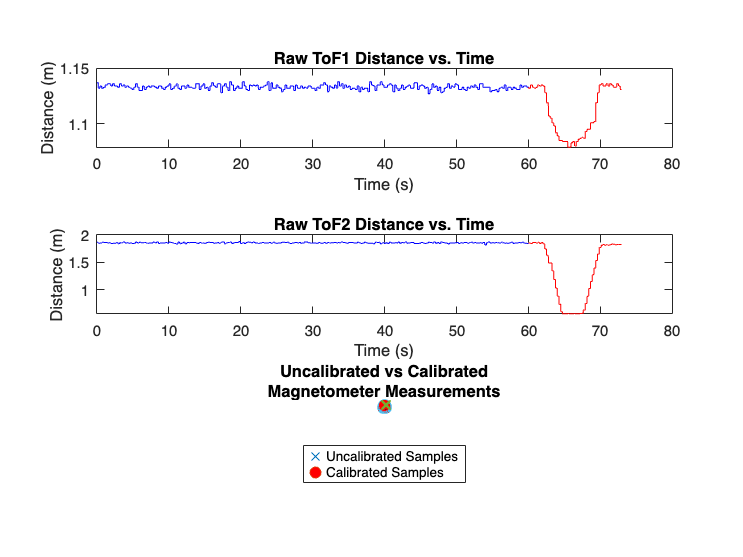


% Check yaw calibration
figure;
subplot(1,2,1); % Plot raw magnetometer ellipse
plot(data_2D(:,1), data_2D(:,2), 'r.');
xlabel('x (T)'); ylabel('y (T)');
title('Raw Magnetometer'); axis equal; grid on;

subplot(1,2,2)
plot(mag_cal_1(:,1), mag_cal_1(:,2), 'r.')
xlabel('x (T)'); ylabel('y (T)');
title('Calibrated Magnetometer'); axis equal; grid on;

%% (OPTIONAL) %%
% Try Matlab magcal
[A,b,expmfs] = magcal(mag_raw); % Calibration coefficients
expmfs; % Display the expected magnetic field strength in uT
C = (mag_raw-b)*A; % Calibrated data
figure(1)
plot3(mag_raw(:,1),mag_raw(:,2),mag_raw(:,3),"LineStyle","none","Marker","X","MarkerSize",8)
hold on
grid(gca,"on")
plot3(C(:,1),C(:,2),C(:,3),"LineStyle","none","Marker","o", ...
      "MarkerSize",8,"MarkerFaceColor","r")
axis equal
xlabel("uT")
ylabel("uT")
zlabel("uT")
legend("Uncalibrated Samples","Calibrated Samples","Location","southoutside")
title("Uncalibrated vs Calibrated" + newline + "Magnetometer Measurements")


A_mag = A

A_mag =      1     0     0
     0     1     0
     0     0     1


b_mag = b

b_mag = 1.0e-04 *

   -0.1037   -0.5304    0.6372


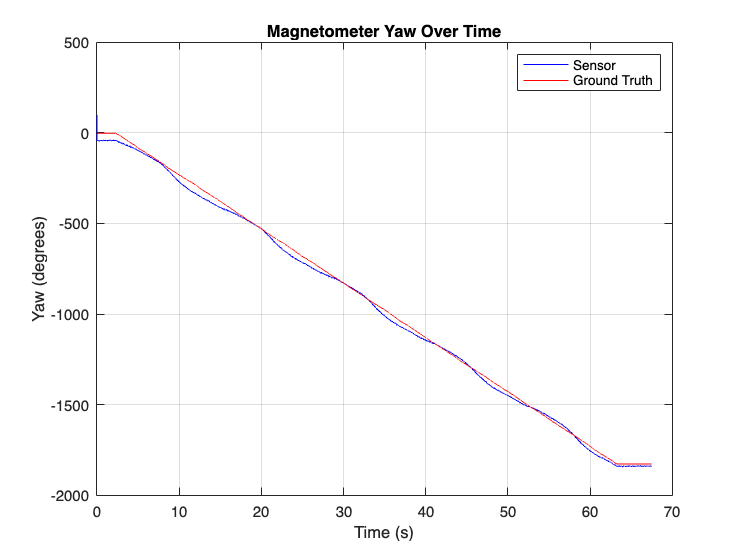

% Load Ground Truth rotation
GT_yaw = rot.out.GT_rotation.signals.values;

% Compare yaw angle of sensor vs. ground truth
yaw_rad = atan2(mag_cal(:,2), mag_cal(:,1));
yaw_unwrapped = unwrap(yaw_rad);
yaw_deg = rad2deg(yaw_unwrapped);

q_GT = quaternion(GT_yaw);
eul = quat2eul(q_GT);
GT_yaw_unwrapped = unwrap(eul(:,1));     % Smooth the angle discontinuities
GT_yaw_deg = rad2deg(GT_yaw_unwrapped);  % Convert to degrees

figure;
plot(time_rot, yaw_deg, 'b', time_rot, GT_yaw_deg, 'r');
xlabel('Time (s)');
ylabel('Yaw (degrees)');
title('Magnetometer Yaw Over Time');
legend('Sensor', 'Ground Truth')
grid on;


% Calculate RMSE
yaw_error = yaw_deg - GT_yaw_deg;
yaw_error = mod(yaw_error + 180, 360) - 180;

rmse_yaw = sqrt(mean(yaw_error.^2));
fprintf('Yaw RMSE: %.2f degrees\n', rmse_yaw);

Yaw RMSE: 23.47 degrees



%% CHECK GENERALIZATION %%
GT_yaw_1 = task1_1.out.GT_rotation.signals.values;

% Compare yaw angle of sensor vs. ground truth
yaw_rad_1 = atan2(mag_cal_1(:,2), mag_cal_1(:,1));
yaw_unwrapped_1 = unwrap(yaw_rad_1);
yaw_deg_1 = rad2deg(yaw_unwrapped_1);
yaw_deg;

q_GT_1 = quaternion(GT_yaw_1);
eul_1 = quat2eul(q_GT_1);
GT_yaw_unwrapped_1 = unwrap(eul_1(:,1));     % Smooth the angle discontinuities
GT_yaw_deg_1 = rad2deg(GT_yaw_unwrapped_1)  % Convert to degrees

GT_yaw_deg_1 =        NaN
  -91.3899
  -91.3899
  -91.3914
  -91.3881
  -91.3885
  -91.3909
  -91.3923
  -91.3928
  -91.3934


GT_yaw_deg

GT_yaw_deg = 1.0e+03 *

   -0.0025
   -0.0025
   -0.0025
   -0.0025
   -0.0025
   -0.0025
   -0.0025
   -0.0025
   -0.0025
   -0.0025



figure;
plot(time_1, yaw_deg_1, 'b', time_1, GT_yaw_deg_1, 'r');
xlabel('Time (s)');
ylabel('Yaw (degrees)');
title('Magnetometer Yaw Over Time');
legend('Sensor', 'Ground Truth')
grid on;

% Calculate RMSE
yaw_error_1 = yaw_deg_1 - GT_yaw_deg_1;
yaw_error_1 = mod(yaw_error_1 + 180, 360) - 180;

rmse_yaw_1 = sqrt(mean(yaw_error_1.^2));
fprintf('Yaw RMSE: %.2f degrees\n', rmse_yaw_1);

Yaw RMSE: NaN degrees


### Output Params

save(outputFileName, 'gyro_bias', 'accel_bias', 'A_mag', 'b_mag', 'tof_bias');
    disp('Calibration successful! Saved parameters for:');

Calibration successful! Saved parameters for:


    disp(['  Accel: ', mat2str(size(accel_bias))]);

  Accel: [1 3]


    disp(['  Gyro: ', mat2str(size(gyro_bias))]);

  Gyro: [1 3]


    disp(['  Magnetometer - A: ', mat2str(size(A_mag)), ', b: ', mat2str(size(b_mag))]);

  Magnetometer - A: [3 3], b: [1 3]


    disp(['  ToF biases: ', mat2str(size(tof_bias))]);

  ToF biases: [1 3]


%% Time-of-Flight %%
function [R_left, R_right, R_front] = plot_reflection_points(ToF_left, ToF_right, ToF_front, Yaw, P, offsets)
    % offsets = [offset_left, offset_right, offset_front]
    ol = offsets(1);
    or = offsets(2);
    of = offsets(3);

    N = length(ToF_left);

    R_left = zeros(N, 2);
    R_right = zeros(N, 2);
    R_front = zeros(N, 2);

    for i = 1:N
        % Sensor positions based on robot pose and yaw
        P_left  = P(i,:) + ol * [-sin(Yaw(i)), cos(Yaw(i))];
        P_right = P(i,:) + or * [sin(Yaw(i)), -cos(Yaw(i))];
        P_front = P(i,:) + of * [cos(Yaw(i)), sin(Yaw(i))];

        % Reflection points
        R_left(i,:)  = P_left  + ToF_left(i)  * [cos(Yaw(i)), sin(Yaw(i))];
        R_right(i,:) = P_right + ToF_right(i) * [cos(Yaw(i)), sin(Yaw(i))];
        R_front(i,:) = P_front + ToF_front(i) * [cos(Yaw(i)), sin(Yaw(i))];
    end

    % Plot
    figure; hold on; axis equal;
    xlim([-3, 3]); ylim([-3, 3]);
    title('ToF Reflection Points with Offset Calibration');
    xlabel('X (m)'); ylabel('Y (m)');

    % Plot arena walls
    plot([-1.2 -1.2], [-1.2 1.2], 'k--');  % left wall
    plot([1.2 1.2], [-1.2 1.2], 'k--');    % right wall
    plot([-1.2 1.2], [1.2 1.2], 'k--');    % front wall (top)

    hold on;
    % Plot robot path
    plot(P(:,1), P(:,2), 'b.', 'LineWidth', 1.5);

    hold on;
    % Plot reflection points
    scatter(R_left(:,1), R_left(:,2), 20, 'r');
    scatter(R_right(:,1), R_right(:,2), 20, 'g');
    scatter(R_front(:,1), R_front(:,2), 20, 'm');

    legend('Robot Path', 'Left ToF', 'Right ToF', 'Front ToF');
    grid on;
end


function rmse = offset_cost_to_arena(offsets, ToF_left, ToF_right, ToF_front, Yaw, P)
    % [offset_left, offset_right, offset_front]
    ol = offsets(1);
    or = offsets(2);
    of = offsets(3);

    % Arena wall positions
    x_left_wall = -1.2;
    x_right_wall = 1.2;
    y_front_wall = 1.2;

    N = length(ToF_left);
    err = zeros(N*3, 1);  % Store all wall errors

    for i = 1:N
        % Sensor positions relative to robot
        P_left  = P(i,:) + ol * [-sin(Yaw(i)), cos(Yaw(i))];
        P_right = P(i,:) + or * [sin(Yaw(i)), -cos(Yaw(i))];
        P_front = P(i,:) + of * [cos(Yaw(i)), sin(Yaw(i))];

        % Reflection points
        R_left  = P_left  + ToF_left(i)  * [cos(Yaw(i)), sin(Yaw(i))];
        R_right = P_right + ToF_right(i) * [cos(Yaw(i)), sin(Yaw(i))];
        R_front = P_front + ToF_front(i) * [cos(Yaw(i)), sin(Yaw(i))];

        % Errors: difference from wall positions
        err(3*(i-1)+1) = abs(R_left(1) - x_left_wall);    % x error to left wall
        err(3*(i-1)+2) = abs(R_right(1) - x_right_wall);  % x error to right wall
        err(3*(i-1)+3) = abs(R_front(2) - y_front_wall);  % y error to front wall
    end

    % Compute RMSE
    rmse = sqrt(mean(err.^2));
end

function filtered = butterworth(data)
    fs = 50;           % Sampling frequency (Hz)
    fc = 0.1;          % Cutoff frequency (Hz)
    order = 2;         % Filter order
    
    Wn = fc/(fs/2);
    [b, a] = butter(order, Wn, 'low');
    
    % Apply zero-phase filtering (no phase shift)
    filtered = filtfilt(b, a, data);
end

%% MAGNETOMETER %%
function [mag_cal, params] = calibrateMagnetometer2D(mag_raw_2D)
% Performs nonlinear ellipse fitting and magnetometer calibration
% using centering, rotation, and normalization

% INPUT:
%   mag_raw_2D - Nx2 matrix of raw [X, Y] magnetometer data
% OUTPUT:
%   mag_cal    - Nx2 calibrated magnetometer data
%   params     - structure with fitted parameters

    epsilon = 1e-10;

    % Normalize for numerical stability
    mu = mean(mag_raw_2D);
    sigma = std(mag_raw_2D);
    mag_norm = (mag_raw_2D - mu) ./ sigma;

    % Initial guess [center_x, center_y, a, b, theta]
    x0 = 0; y0 = 0; a0 = 1; b0 = 1; theta0 = 0;
    p0 = [x0, y0, a0, b0, theta0];

    % Residual function: how far each point is from the ellipse surface
    residuals = @(p) ...
        ((( (mag_norm(:,1) - p(1)) * cos(p(5)) + (mag_norm(:,2) - p(2)) * sin(p(5))) / max(p(3), epsilon)).^2 + ...
         ((-(mag_norm(:,1) - p(1)) * sin(p(5)) + (mag_norm(:,2) - p(2)) * cos(p(5))) / max(p(4), epsilon)).^2 - 1);

    % Bounds to constrain optimization
    lb = [-2, -2, 0.1, 0.1, -pi];
    ub = [ 2,  2, 5.0, 5.0,  pi];

    % Optimization options
    opts = optimoptions('lsqnonlin', 'Display', 'off', 'MaxIterations', 1000);

    % Run optimization
    p_opt = lsqnonlin(residuals, p0, lb, ub, opts);

    % Extract parameters
    offset_norm = p_opt(1:2);
    a = max(p_opt(3), epsilon);
    b = max(p_opt(4), epsilon);
    theta = p_opt(5);

    % De-normalize center
    offset = offset_norm .* sigma + mu;

    % Construct rotation and scaling matrices
    R = [cos(theta), sin(theta); -sin(theta), cos(theta)];  % Rotation
    S = diag([1/a, 1/b]);                                   % Inverse scaling

    % Final transformation matrix (in normalized space)
    T_norm = S * R;

    % Apply calibration: center, normalize, rotate
    mag_centered = mag_raw_2D - offset;
    mag_cal = (T_norm * ((mag_centered ./ sigma)'))';  % Back to calibrated space

    % Output params
    params.offset = offset;
    params.softIronMatrix = T_norm;
    params.rotation = R;
    params.scaling = S;
    params.ellipse = p_opt;
end

function mag_cal = calibrate_mag_params(params, data)
    vector = data(:,1:2);
    sigma = std(vector);
    
    % Apply calibration: hard iron and soft iron
    mag_centered = vector - params.offset;
    mag_cal = (params.softIronMatrix * ((mag_centered ./ sigma)'))'
end

%% GYROSCOPE %%
function rmse_gyro = gyro_bias_cost(bias, raw_gyro, dt, ground_truth_q, q0)
    calibrated_gyro = raw_gyro - bias;
end
